clc;clear;
dx=.01;     % increementos
x=-2*pi:dx:2*pi; % rango x

Función(es):

y1=sinc(x+pi/3);
plot(x,y1,'LineWidth',2);
grid; axis([-9,9,-.3,1.2]);
[m,xm]=max(y1);
[miny1,xmin]=min(y1)

miny1 = -0.2172

xmin = 668

x(xm)

ans = -1.0432

%line([x(xm),x(xm)],[-9,9],'color',[0 0 0],'LineWidth',3)
hold on
plot(x(xm),m,'LineWidth',4,'Marker','o')


# **Ciclo for**

for i = 10:-.5:7
    i;
end

Otros casos

dx=0.01;
x=-2*pi:dx:2*pi; % rango x
y1=sinc(x+pi/3);
minimosY = [];      minimosX = []


minimosX =

     []



minimo = y1(1);
for i = 2:length(x)-1       % for i = 1:length(x) ó for i = 0:length(x)-1
%     if y1(i)<minimo
%         if y1(i)<y1(i+1)
%             minimo = y1(i);
%             x_minimo = x(i);
%             minimosY = [minimosY minimo];
%             minimosX = [minimosX x_minimo];
%             % plot(x_minimo,minimo,'LineWidth',4,'Marker','o')
%         end
%     end
    if y1(i-1)>y1(i) & y1(i+1)>y1(i)
        minimo = y1(i);
        x_minimo = x(i)
        minimosY = [minimosY minimo];
        minimosX = [minimosX x_minimo];
        % plot(x_minimo,minimo,'LineWidth',4,'Marker','o')
    end
end

x_minimo = -4.5132

x_minimo = -2.4732

x_minimo = 0.3868

x_minimo = 2.4268

x_minimo = 4.4368

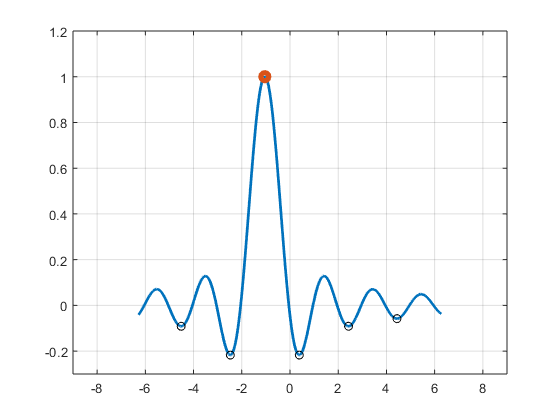

% vpa(minimo,8)
% plot(x_minimo,minimo,'LineWidth',4,'Marker','o')
plot(minimosX,minimosY,'ko')

minimosX

minimosX =    -4.5132   -2.4732    0.3868    2.4268    4.4368


minimosY

minimosY =    -0.0913   -0.2172   -0.2172   -0.0913   -0.0580
